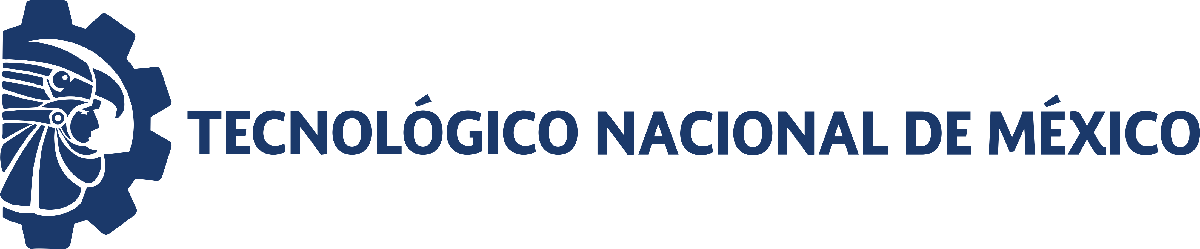                                 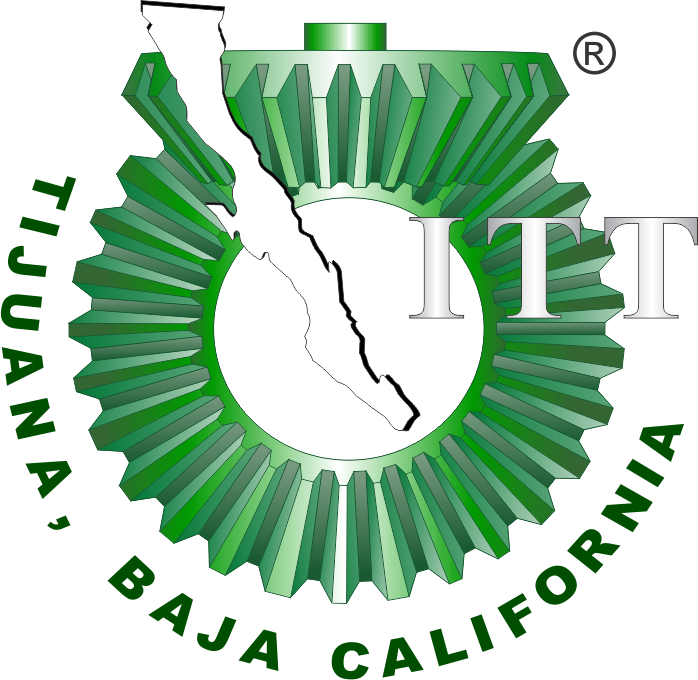

# Práctica uno: Diseño de controlador para un sistema de segundo orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

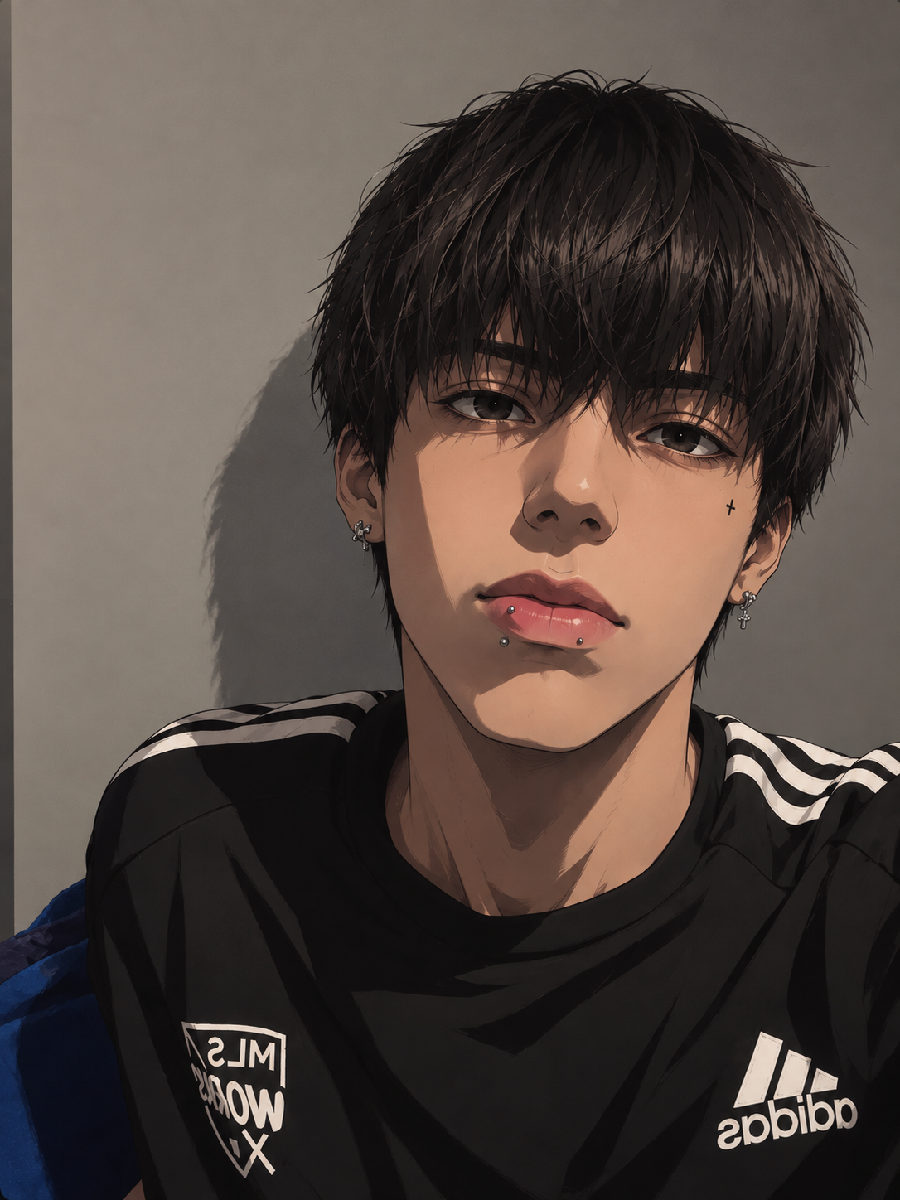

Nombre del alumno: Armenta Medina Osmar Ediel

Número de control: 23212178

Correo institucional: l23212178**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
% set_param('sistema/PpL(t): CE/PpL','VectorFormat','1D-array');
x = sim('sistema',parameters);
t_data = (0:0.1:15)';
t = (0:0.01:15)';
Pa = interp1(t_data, x.Pa, t, 'previous');
% writematrix(Pa,'C:\Users\ediel\OneDrive\Escritorio\modelado\Unidad 3\signal.xlsx');

## Normotenso

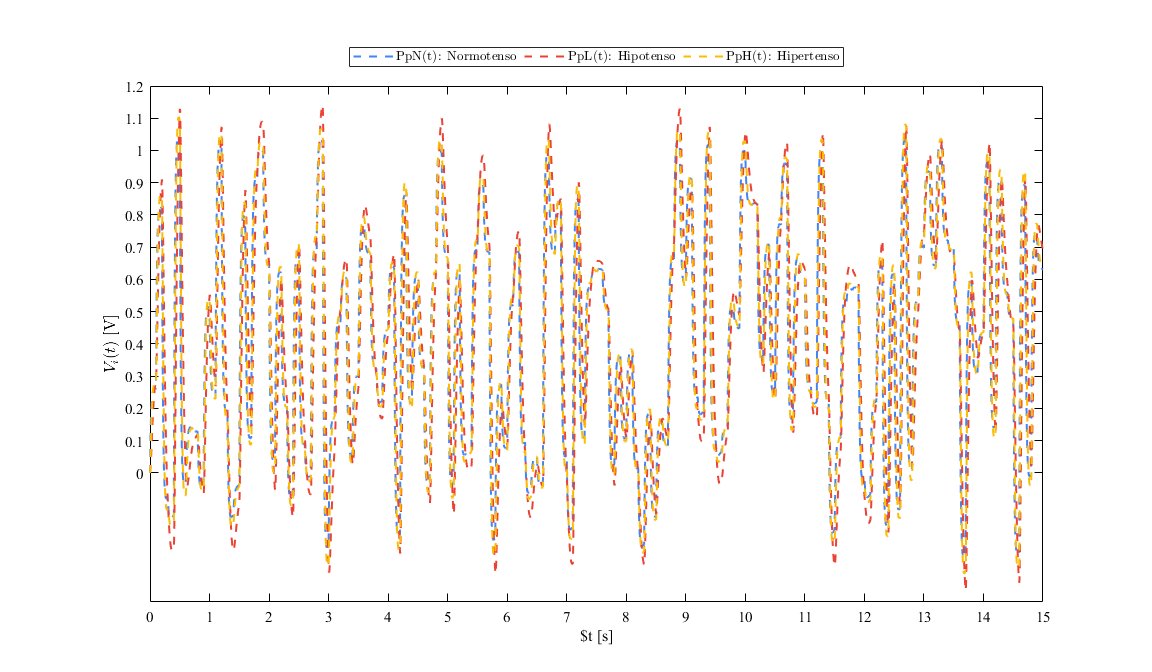

x = sim('sistema',parameters);
plotsignals(x.t,x.PpN,x.PpL,x.PpH, "individuos")  

## Hipotenso

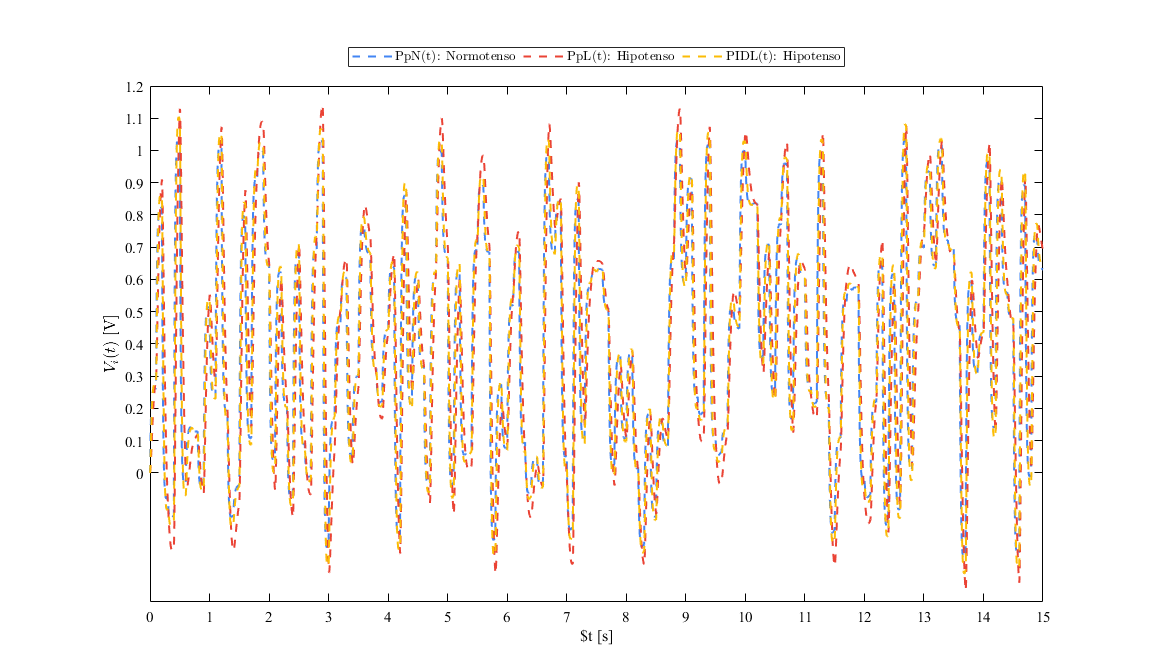

x1 = sim('sistema',parameters);
plotsignals(x1.t,x1.PpN,x1.PpL,x1.PpH, "Hipotenso")

## Hipertenso

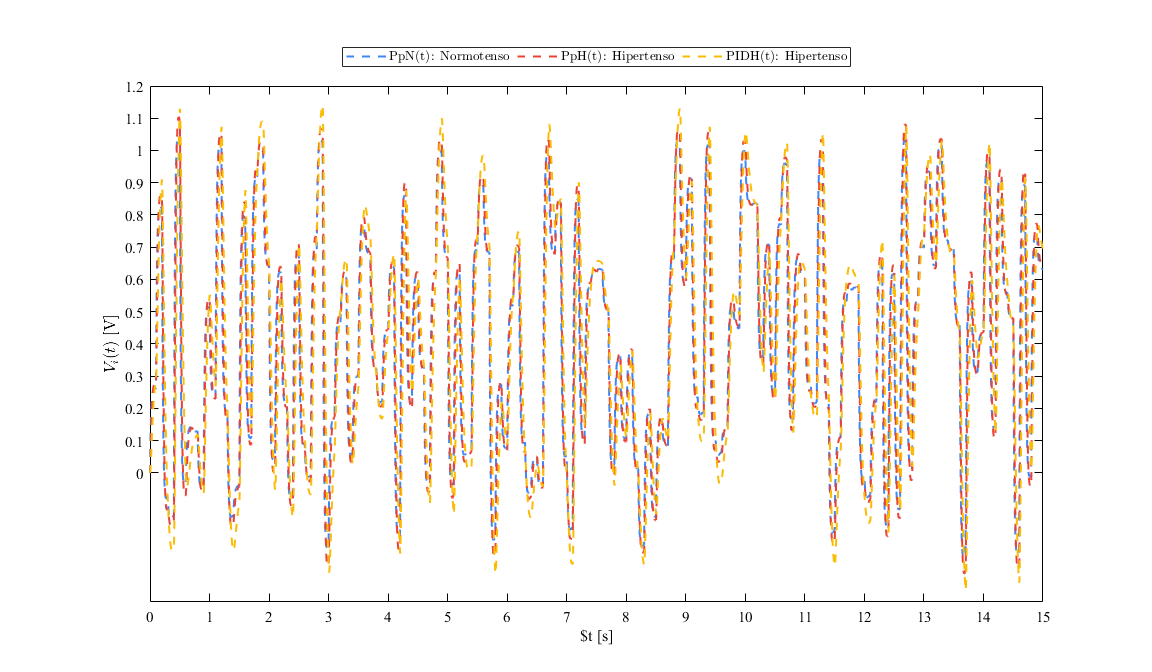

x2 = sim('sistema',parameters);
plotsignals(x2.t,x2.PpN,x2.PpL,x2.PpH, "Hipertenso")

## Modelo de EDOs

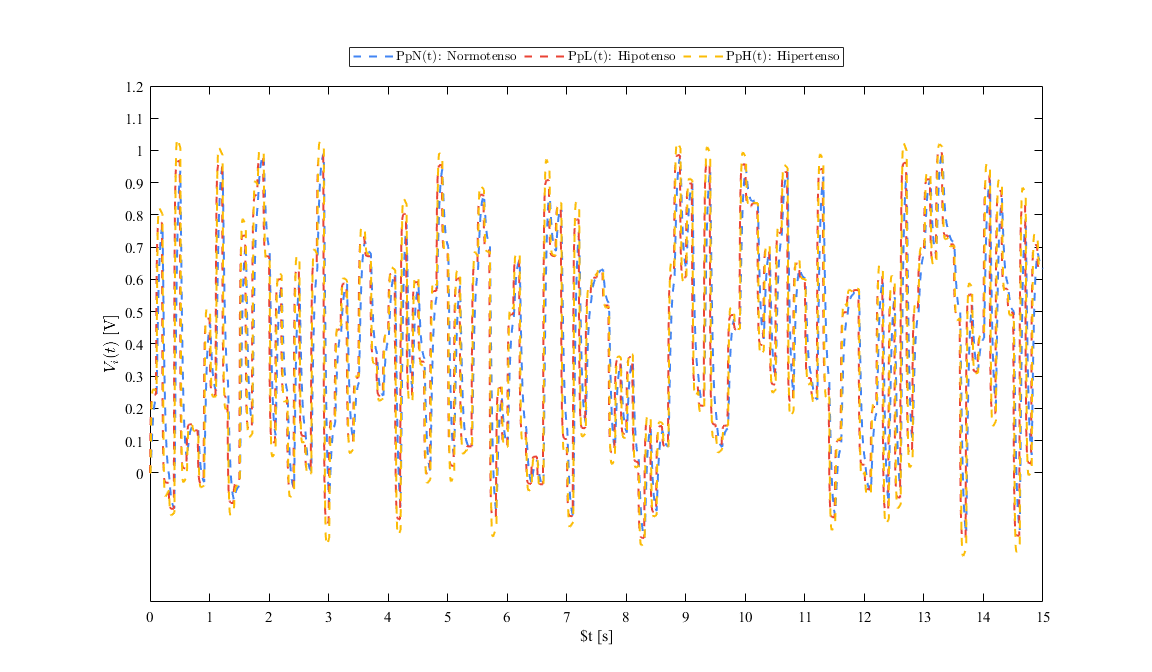

parameters_hipo = [0.010, 0.01,1.00, 3.500];
parameters_normo = [0.010,0.01,1.000,1.500];
par_hiper = [0.010, 0.001, 1.000,1.000];
PpN = cardio(parameters_normo,Pa,t);
PpL = cardio(parameters_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotsignals(t,PpL,PpN,PpH,'individuos');

function Pp = cardio(par, Pa, t)
Z = par(1); L = par(2); R = par(3); C = par(4); dt = t(2);
n = round(t(end)/dt);

FL = zeros(length(t),1); FL(1) = 0;
Pp = zeros(length(t),1); Pp(1) = 0;

for i = 1:n
    FL(i+1) = FL(i) + (-(1/L*Pp(i)) + (1/L)*Pa(i))*dt;
    Pp(i+1) = Pp(i) + ((1/C)*FL(i) - (1/(Z*C) + 1/(R*C))*Pp(i)+1/(Z*C)*Pa(i))*dt;
end
end

## Funcion: Respuestas de la simulacion 

function plotsignals(t,PpN,PpL,PpH,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [0.5,0.5,12,7])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [66, 133, 244]/255;  
    clr2 = [234, 67, 53]/255;   
    clr3 = [251, 188, 5]/255;   
    order = [clr1; clr2; clr3]; colororder(order)


    xlabel('$t [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]', 'Interpreter','latex')

    xlim([0 15]); xticks(0:1:15)
    ylim([-0.4 1.2]); yticks(0:0.1:1.2)

    if signal == "individuos"

        plot(t,PpN,'--',t,PpL,'--',t,PpH,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('PpN(t): Normotenso','PpL(t): Hipotenso','PpH(t): Hipertenso');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
        
          
    elseif signal == "Hipotenso"
        plot(t,PpN,'--',t,PpL,'--',t,PpH,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('PpN(t): Normotenso','PpL(t): Hipotenso','PIDL(t): Hipotenso');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
       

 
    elseif signal == "Hipertenso"
        plot(t,PpN,'--',t,PpH,'--',t,PpL,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('PpN(t): Normotenso','PpH(t): Hipertenso','PIDH(t): Hipertenso');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
  

    end
    set(gcf,'Color','white')
    set(gca,'Color','white','XColor','black','YColor','black')
    set(L,'Color','white','TextColor','black')

    
end